# Part 1

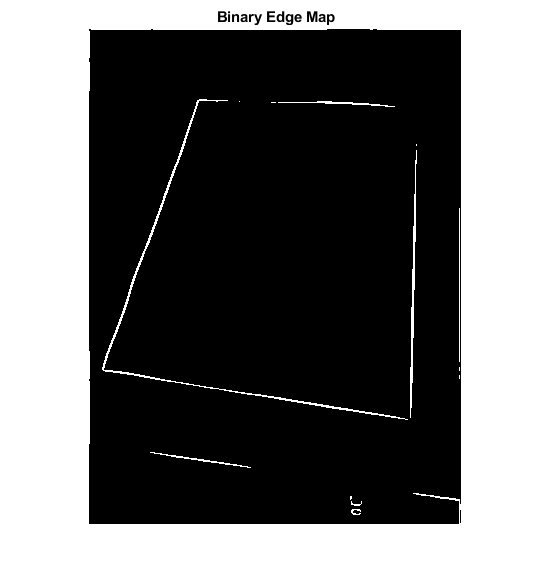

clear; clc;
image = imread('paperExample.jpg');
gray_image = rgb2gray(image);

smoothing_kernel = (1/9) * ones(3, 3); 
edge_kernel_x = [-1, 0, 1; -2, 0, 2; -1, 0, 1];  
edge_kernel_y = [-1, -2, -1; 0, 0, 0; 1, 2, 1];  

smoothed_image = conv2(double(gray_image), smoothing_kernel, 'same');
gradient_x = conv2(smoothed_image, edge_kernel_x, 'same');
gradient_y = conv2(smoothed_image, edge_kernel_y, 'same');

gradient_magnitude = sqrt(gradient_x.^2 + gradient_y.^2);

threshold = 300; 
edge_map = gradient_magnitude > threshold;

figure;
imshow(edge_map); title('Binary Edge Map');

imwrite(edge_map, 'edge_map.jpg');


## Part 2

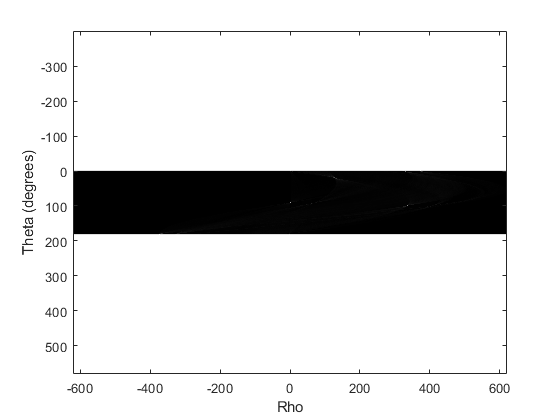


% Initialize Hough accumulator parameters
theta_step = 1;  % Adjust the step size for theta as needed
rho_step = 1;    % Adjust the step size for rho as needed
max_rho = round(hypot(size(gray_image, 1), size(gray_image, 2)));

% Initialize Hough accumulator
theta_range = 0:theta_step:180;
rho_range = -max_rho:rho_step:max_rho;
hough_accumulator = zeros(length(theta_range), length(rho_range));

% Loop through edge pixels and accumulate votes
[y_coords, x_coords] = find(edge_map);
num_points = length(x_coords);

for i = 1:num_points
    x = x_coords(i);
    y = y_coords(i);
    
    for theta_index = 1:length(theta_range)
        theta = deg2rad(theta_range(theta_index));
        rho = round(x * cos(theta) + y * sin(theta));
        rho_index = round((rho + max_rho) / rho_step) + 1;
        
        % Update the Hough accumulator
        hough_accumulator(theta_index, rho_index) = hough_accumulator(theta_index, rho_index) + 1;
    end
end

% Visualize the Hough accumulator as an image
figure;
imagesc(rho_range, theta_range, hough_accumulator);
colormap(gca, gray);  % You can change the colormap as needed

% Label axes and set aspect ratio
xlabel('Rho');
ylabel('Theta (degrees)');
axis on;
axis equal;

% Find and display the peaks in the Hough accumulator (optional)
peaks = houghpeaks(hough_accumulator, 5);  % Adjust the number of peaks as needed
hold on;

%plot(rho_range(peaks(:, 2)), theta_range(peaks(:, 1)), 'ro', 'MarkerSize', 10);


## Part 3

% Define your threshold (adjust as needed)
threshold = 300;

% Find local maxima in the Hough accumulator
potential_lines = zeros(0, 2);  % Initialize an empty array to store (𝜃, 𝑟) pairs

for theta_index = 1:length(theta_range)
    for rho_index = 1:length(rho_range)
        current_value = hough_accumulator(theta_index, rho_index);
        
        if current_value <= threshold
            continue;  % Skip values below the threshold
        end

        % Check if it's a local maximum within a window size
        is_local_max = true;
        for i = -1:1
            for j = -1:1
                if (i == 0 && j == 0)
                    continue;  % Skip the central pixel
                end
                
                neighbor_value = hough_accumulator(theta_index + j, rho_index + i);
                if current_value <= neighbor_value
                    is_local_max = false;
                    break;
                end
            end
            if ~is_local_max
                break;
            end
        end

        if is_local_max
            % Store the (𝜃, 𝑟) pair as a potential line
            potential_lines = [potential_lines; theta_range(theta_index), rho_range(rho_index)];
        end
    end
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.


% Enforce constraints (e.g., angle, separation, length, parallel)
% Implement constraint checks and filter potential_lines accordingly

% Draw the detected lines on the original edge image
figure;
imshow(edge_map);
hold on;

for i = 1:size(potential_lines, 1)
    theta = deg2rad(potential_lines(i, 1));
    rho = potential_lines(i, 2);
    x1 = 0;
    x2 = size(image, 2);
    y1 = (rho - x1 * cos(theta)) / sin(theta);
    y2 = (rho - x2 * cos(theta)) / sin(theta);
    
    % Plot the line
    plot([x1, x2], [y1, y2], 'r', 'LineWidth', 1);
end

hold off;


## Part 4

% Find intersections of potential lines
intersections = [];

for i = 1:size(potential_lines, 1)
    for j = i+1:size(potential_lines, 1)
        theta1 = deg2rad(potential_lines(i, 1));
        rho1 = potential_lines(i, 2);
        theta2 = deg2rad(potential_lines(j, 1));
        rho2 = potential_lines(j, 2);
        
        % Compute the intersection point
        A = [cos(theta1), sin(theta1); cos(theta2), sin(theta2)];
        b = [rho1; rho2];
        intersection_point = A \ b;
        x_intersect = intersection_point(1);
        y_intersect = intersection_point(2);
        
        % Check if the intersection point is within the image boundaries
        if x_intersect >= 1 && x_intersect <= size(image, 2) && y_intersect >= 1 && y_intersect <= size(image, 1)
            intersections = [intersections; x_intersect, y_intersect];
        end
    end
end

% Determine the four corner points by selecting the extreme points
if ~isempty(intersections)
    % Sort intersections by x-coordinate
    sorted_intersections = sortrows(intersections, 1);
    
    % Get the leftmost and rightmost points
    leftmost_point = sorted_intersections(1, :);
    rightmost_point = sorted_intersections(end, :);
    
    % Sort intersections by y-coordinate
    sorted_intersections = sortrows(intersections, 2);
    
    % Get the topmost and bottommost points
    topmost_point = sorted_intersections(1, :);
    bottommost_point = sorted_intersections(end, :);
    
    % Superimpose corners on the image
    figure;
    imshow(image);
    hold on;
    
    % Plot the corners
    plot(leftmost_point(1), leftmost_point(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    plot(rightmost_point(1), rightmost_point(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    plot(topmost_point(1), topmost_point(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    plot(bottommost_point(1), bottommost_point(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    
    hold off;
    
end

## Part 5

originalPoints = [leftmost_point;topmost_point;rightmost_point; bottommost_point];
% Calculate the dimensions for the blank image
[heightPixels, widthPixels, numberOfColorChannels] = size(image);



% Create a blank image
blankImage = uint8(zeros(heightPixels, widthPixels, 3));  % Assuming it's a color image (RGB)

% Define the four corner points in the original image
%originalPoints = [x1, y1; x2, y2; x3, y3; x4, y4];

% Define the corresponding points in the blank image (corners)
blankPoints = [0, 0; widthPixels, 0; widthPixels, heightPixels; 0, heightPixels];

% Calculate the homography matrix
H = calculateHomographyMatrix(blankPoints, originalPoints); % You need to implement this function

% Loop through each location in the blank image
for y = 1:heightPixels
    for x = 1:widthPixels
        % Calculate the corresponding location in the original image
        originalLocation = H * [x; y; 1];
        originalX = originalLocation(1) / originalLocation(3);
        originalY = originalLocation(2) / originalLocation(3);
        
        % Copy the pixel value from the original image to the rectified image
        if originalX >= 1 && originalX <= size(image, 2) && originalY >= 1 && originalY <= size(image, 1)
            blankImage(y, x, :) = image(round(originalY), round(originalX), :);
        end
    end
end

% Display the rectified image
imshow(blankImage);





function H = calculateHomographyMatrix(points1, points2)
    % Ensure points1 and points2 have the same number of points (at least 4).
    assert(size(points1, 1) == size(points2, 1) && size(points1, 1) >= 4, 'Invalid input.');

    numPoints = size(points1, 1);

    % Create matrices to build the linear system of equations
    A = zeros(2 * numPoints, 9);

    for i = 1:numPoints
        X1 = points1(i, 1);
        Y1 = points1(i, 2);
        X2 = points2(i, 1);
        Y2 = points2(i, 2);

        A(2 * i - 1, :) = [-X1, -Y1, -1, 0, 0, 0, X1 * X2, Y1 * X2, X2];
        A(2 * i, :) = [0, 0, 0, -X1, -Y1, -1, X1 * Y2, Y1 * Y2, Y2];
    end

    % Use Singular Value Decomposition to solve for the homography matrix
    [~, ~, V] = svd(A);
    h = V(:, 9);

    % Reshape the column vector h into the 3x3 homography matrix H
    H = reshape(h, [3, 3])';
end
